# Image Thresholding

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2021-01-02

### **Otsu's Method (Example)**

img = imread('coins.png');
T = graythresh(img);
figure;
subplot(121); imhist(img);
subplot(122); imshow(im2double(img)>T);

### **Otsu's Method**

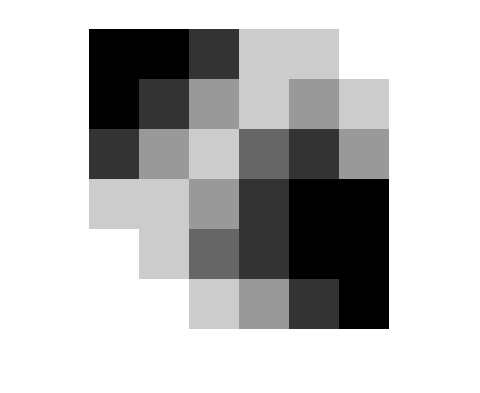

% test image (6 level);
img = [1 1 2 5 5 6;1 2 4 5 4 5;2 4 5 3 2 4;5 5 4 2 1 1;6 5 3 2 1 1;6 6 5 4 2 1]; 

L = 6; % 6 gray level

N = size(img,1) * size(img,2);

figure; imshow(mat2gray(repelem(img, 50,50))); % for visualization using repelem (because the original image is too small.)

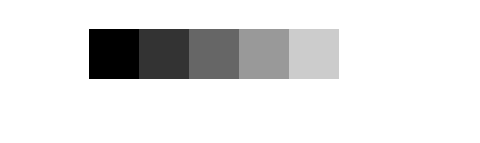


figure; imshow(mat2gray(repelem(1:6,50,50)));

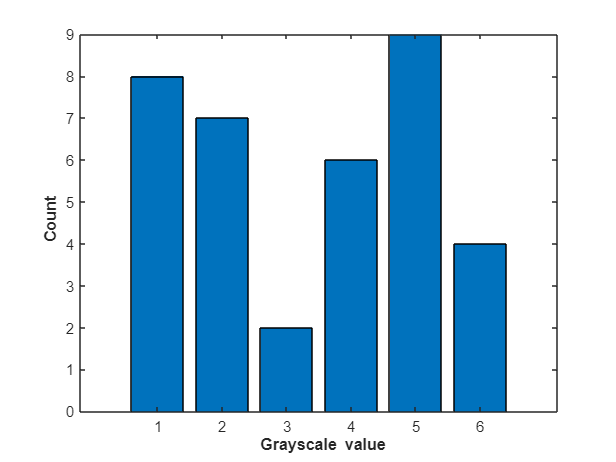


% compute histogram (ni)
ni = zeros(1, L);
for ii=1:L
    ni(ii) = sum(img==ii,'all'); % the number of pixels at level i
end

figure; bar(ni); % draw histogram
ylabel('\bf Count');
xlabel('\bf Grayscale value');


pi = ni/N; % probability distribution

% probability of class occurence
w0 = @(k) sum(pi(1:k));
w1 = @(k) 1-w0(k);

% class mean level
u0 = @(k) 1/w0(k)*sum(pi(1:k).*(1:k));
u1 = @(k) 1/w1(k)*sum(pi((k+1):L).*((k+1):L));
uT = sum(pi.*(1:L));

% class variance
sig0 = @(k) 1/w0(k)*sum(pi(1:k).*((1:k)- u0(k)).^2);
sig1 = @(k) 1/w1(k)*sum(pi((k+1):L).*(((k+1):L) - u1(k)).^2);

% otsu method
sigW = @(k) w0(k)*sig0(k) + w1(k)*sig1(k);
sigB = @(k) w0(k)*w1(k)*(u0(k)-u1(k)).^2;

sigT = sum(pi.*((1:L)-uT).^2);

% k == 2
k = 2;
fprintf("W0 is %f. \n", w0(k));

W0 is 0.416667. 


fprintf("W1 is %f. \n", w1(k));

W1 is 0.583333. 


fprintf("uT is %f. \n", uT);

uT is 3.361111. 


fprintf("u0 is %f. \n", u0(k));

u0 is 1.466667. 


fprintf("u1 is %f. \n", u1(k));

u1 is 4.714286. 


fprintf("sigma0 is %f. \n", sig0(k));

sigma0 is 0.248889. 


fprintf("sigma1 is %f. \n", sig1(k));

sigma1 is 0.775510. 


fprintf("sigmaT is %f. \n", sigT);

sigmaT is 3.119599. 



disp(u0(k)*w0(k) + u1(k)*w1(k));

    3.3611



disp(uT);

    3.3611




disp(sigW(k) + sigB(k));

    3.1196



disp(sigT);

    3.1196



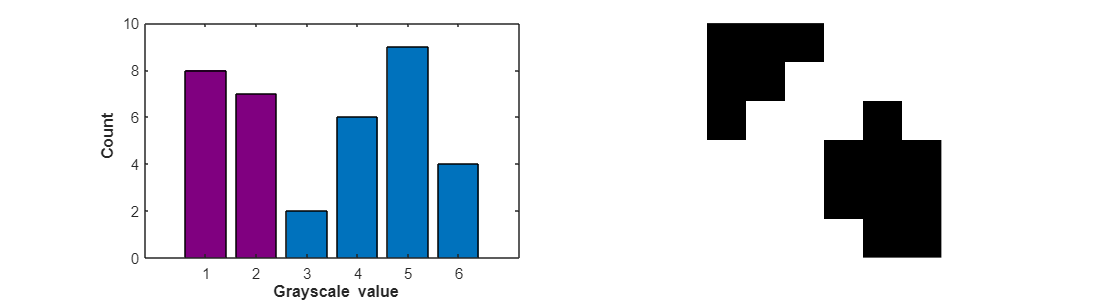


fig1 = figure(1); set(fig1,'Position', [100 100 1100 300]);
subplot(121);
b = bar(ni); % draw histogram
b.FaceColor = 'flat';
b.CData(1:k,:) = ones(k,1)*[0.5 0 0.5];
ylabel('\bf Count');
xlabel('\bf Grayscale value');

subplot(122);
imgBW = zeros(size(img));
imgBW(img >= (k+1)) = 1;
imshow(mat2gray(repelem(imgBW, 50,50))); % for visualization using repelem (because the original image is too small.)


% k == 4
k = 4;
fprintf("W0 is %f. \n", w0(k));

W0 is 0.638889. 


fprintf("W1 is %f. \n", w1(k));

W1 is 0.361111. 


fprintf("uT is %f. \n", uT);

uT is 3.361111. 


fprintf("u0 is %f. \n", u0(k));

u0 is 2.260870. 


fprintf("u1 is %f. \n", u1(k));

u1 is 5.307692. 


fprintf("sigma0 is %f. \n", sig0(k));

sigma0 is 1.410208. 


fprintf("sigma1 is %f. \n", sig1(k));

sigma1 is 0.213018. 


fprintf("sigmaT is %f. \n", sigT);

sigmaT is 3.119599. 



disp(u0(k)*w0(k) + u1(k)*w1(k));

    3.3611



disp(uT);

    3.3611




disp(sigW(k) + sigB(k));

    3.1196



disp(sigT);

    3.1196



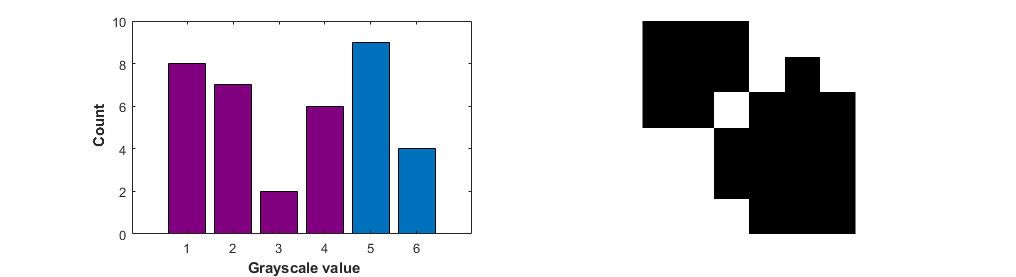


fig2 = figure(2); set(fig2,'Position', [100 100 1100 300]);
subplot(121);
b = bar(ni); % draw histogram
b.FaceColor = 'flat';
b.CData(1:k,:) = ones(k,1)*[0.5 0 0.5];
ylabel('\bf Count');
xlabel('\bf Grayscale value');

subplot(122);
imgBW = zeros(size(img));
imgBW(img >= (k+1)) = 1;
imshow(mat2gray(repelem(imgBW, 50,50))); % for visualization using repelem (because the original image is too small.)

sigmaW is 1.526786. 


sigmaB is 1.592813. 


sigmaW is 0.556085. 


sigmaB is 2.563514. 


sigmaW is 0.490884. 


sigmaB is 2.628715. 


sigmaW is 0.977889. 


sigmaB is 2.141710. 


sigmaW is 2.249132. 


sigmaB is 0.870467. 


sigmaW is NaN. 


sigmaB is NaN. 


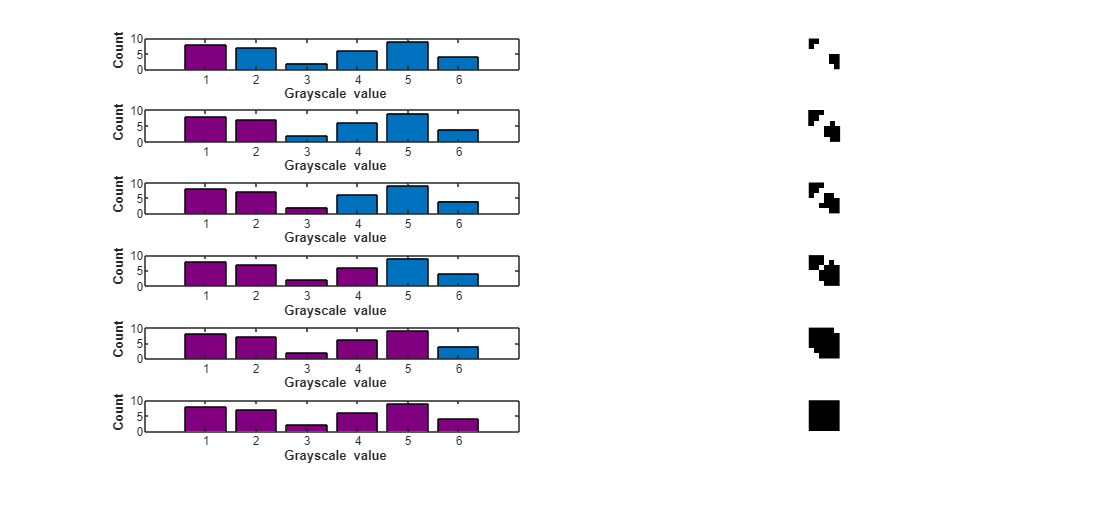


fig3 = figure(3); set(fig3,'Position', [100 100 1100 500]);
for k=1:L
    subplot(L,2,2*(k-1)+1);
    b = bar(ni); % draw histogram
    b.FaceColor = 'flat';
    b.CData(1:k,:) = ones(k,1)*[0.5 0 0.5];
    ylabel('\bf Count');
    xlabel('\bf Grayscale value');
    
    fprintf("sigmaW is %f. \n", sigW(k));
    fprintf("sigmaB is %f. \n", sigB(k));
    
    fprintf("=============");
    
    subplot(L,2,2*k);
    imgBW = zeros(size(img));
    imgBW(img >= (k+1)) = 1;
    imshow(mat2gray(repelem(imgBW, 50,50))); % for visualization using repelem (because the original image is too small.)
end

### **Marker Detection**

imgo = imread('CaptureImage13.jpg');

imgo = imresize(imgo,0.2);

img = rgb2gray(imgo);

T = adaptthresh(img,0.4);
BW = ~imbinarize(img, T);

[B, L] = bwboundaries(BW, 'noholes');

valid_id = zeros(1,numel(B));
area_thres = 100;
for ii=1:numel(B)
    val = sum(L==ii,'all');
    valid_id(ii) =  val > 100 && val < prod(size(BW))*0.5;
end

B(~valid_id) = [];

figure;imshow(img); hold on;
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end; hold off;

Br = cell(size(B));
for ii=1:numel(B)
    Br{ii} = reducepoly(B{ii},0.1);
end

figure;imshow(img); hold on;
for k = 1:length(Br)
   boundary = Br{k};
   plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end; hold off;

